## Task 3

% 3.d.
P = 100000;                               % Stopping criterion
C = 10;                                   % Link capacity in Mbps
lambda = 1500;                            % Values for packet rate in pps
f = 10000;                                % Queue size(in bytes)

N = 20;                                   % number of simulation
n = [10, 20, 30, 40];                     % number of adidional VoIP packets flows

pkt_delay_voip = zeros(1, length(lambda));
error_delay_voip = zeros(1, length(lambda));
pkt_loss_voip = zeros(1, length(lambda)); 
error_loss_voip = zeros(1, length(lambda)); 

pkt_delay_data = zeros(1, length(lambda));
error_delay_data = zeros(1, length(lambda));
pkt_loss_data = zeros(1, length(lambda));  
error_loss_data = zeros(1, length(lambda));  

AVERAGE = zeros(4,4);
TERM = zeros(4,4);

for j = 1:length(n)
    PLd = zeros(1, N);
    PLv = zeros(1, N);
    APDd = zeros(1, N);
    APDv = zeros(1, N);
    MPDd = zeros(1, N);
    MPDv = zeros(1, N);
    TT = zeros(1, N);
    
    for i = 1:N
        [PLd(i), PLv(i), APDd(i), APDv(i), MPDd(i), MPDv(i), TT(i)] = Simulator4B(lambda,C,f,P,n(j));
    end    
    alfa = 0.1; % 90% confidence interval 
    
    
    AVERAGE = mean(PLd);
    TERM = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    fprintf("Packet Loss (%%)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss_data(j) = AVERAGE;
    error_loss_data(j) = TERM;

    AVERAGE = mean(APDd);
    TERM = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    fprintf("Av. Packet Delay Data (ms)  = %.2e +- %.2e\n\n\n", AVERAGE, TERM);
    pkt_delay_data(j) = AVERAGE;
    error_delay_data(j) = TERM;

    AVERAGE = mean(PLv);
    TERM = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    fprintf("Packet Loss VoIP (%%)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss_voip(j) = AVERAGE;
    error_loss_voip(j) = TERM;

    AVERAGE = mean(APDv);
    TERM = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    fprintf("Av. Packet Delay VoIP (ms)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_delay_voip(j) = AVERAGE;
    error_delay_voip(j) = TERM;
 
end

Packet Loss (%)  = 2.32e-01 +- 1.13e-02


Av. Packet Delay Data (ms)  = 2.09e+00 +- 1.15e-02




Packet Loss VoIP (%)  = 3.86e-01 +- 2.37e-02


Av. Packet Delay VoIP (ms)  = 4.60e-01 +- 1.06e-03


Packet Loss (%)  = 3.92e-01 +- 1.70e-02


Av. Packet Delay Data (ms)  = 2.51e+00 +- 1.76e-02




Packet Loss VoIP (%)  = 6.50e-01 +- 3.02e-02


Av. Packet Delay VoIP (ms)  = 4.81e-01 +- 1.04e-03


Packet Loss (%)  = 6.91e-01 +- 2.76e-02


Av. Packet Delay Data (ms)  = 3.07e+00 +- 2.25e-02




Packet Loss VoIP (%)  = 1.14e+00 +- 3.78e-02


Av. Packet Delay VoIP (ms)  = 5.02e-01 +- 1.10e-03


Packet Loss (%)  = 1.16e+00 +- 4.49e-02


Av. Packet Delay Data (ms)  = 3.82e+00 +- 3.38e-02




Packet Loss VoIP (%)  = 1.89e+00 +- 6.33e-02


Av. Packet Delay VoIP (ms)  = 5.24e-01 +- 1.27e-03


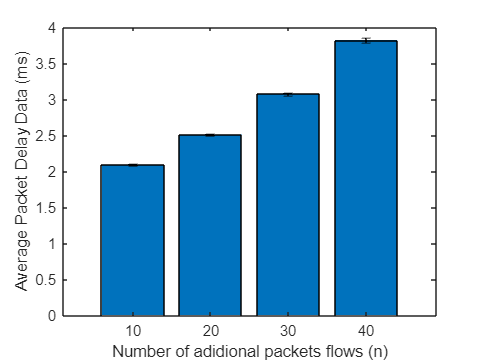



% Plot the results
figure(1)
bar(categorical(n), pkt_delay_data)
title("Queue with VoIP Packets")
xlabel("Number of adidional packets flows (n)")
ylabel("Average Packet Delay Data (ms)")
hold on
er = errorbar(categorical(n), pkt_delay_data, error_delay_data, error_delay_data);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

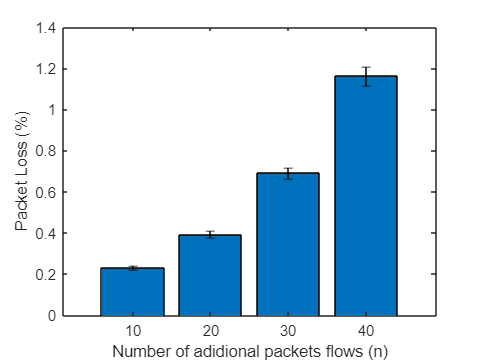


%%% Plot the results
figure(2)
bar(categorical(n), pkt_loss_data)
title("Queue with VoIP Packets")
xlabel("Number of adidional packets flows (n)")
ylabel("Packet Loss (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(n), pkt_loss_data, error_loss_data, error_loss_data);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

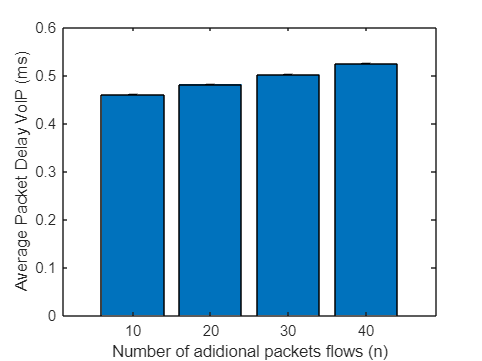


% Plot the results
figure(3)
bar(categorical(n), pkt_delay_voip)
title("Queue with VoIP Packets")
xlabel("Number of adidional packets flows (n)")
ylabel("Average Packet Delay VoIP (ms)")
hold on
er = errorbar(categorical(n), pkt_delay_voip, error_delay_voip, error_delay_voip);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

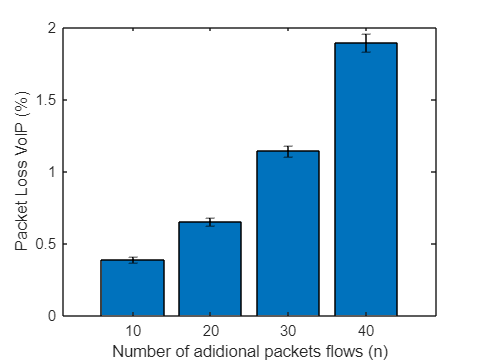


%%% Plot the results
figure(4)
bar(categorical(n), pkt_loss_voip)
title("Queue with VoIP Packets")
xlabel("Number of adidional packets flows (n)")
ylabel("Packet Loss VoIP (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(n), pkt_loss_voip, error_loss_voip, error_loss_voip);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

%{ 
conclusão:  
Quando o total da ocupação de pacotes na fila não são maiores do que 90%, não há perdas
em pacotes dados transmitidos via VoIP quando os data pkts são aceites na fila.
Porém nota-se perdas significativas de pacotes quando os VoIP pkts são aceites na fila.   
%}

